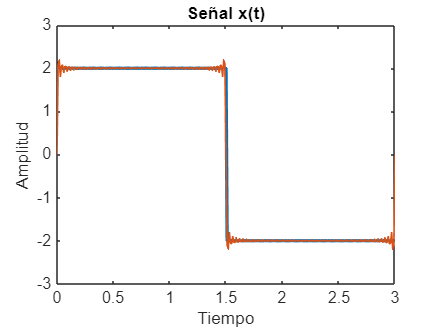

clear variables; %Eliminar las variables generadas 
close all; %Cerrar las ventanas abiertas 
clc; %Limpia el Comnand Window 

%Parámetros del Muestreador 
T = 0.01; %Periodo de muestreo (s - tiempo entre muestra) 
Fs = 1/T; %Frecuencia de muestreo (Hz - o muestras por segundo) 
t = 0:T:3; %Vector Tiempo 
x = 2*(t>=0 & t<=1.5) -2*(t>1.5 & t<=3); 
figure(); 
plot(t,x,LineWidth=2); 
xlim([0 3]); ylim([-3 3]);
title("Señal x(t)");xlabel("Tiempo");
ylabel("Amplitud");

hold on;

fx = 0;

for n=1: 100
    bn = (2*cos(2*pi*n)-4*cos(pi*n)+2)/(pi*n);
    fx = fx + bn*sin(2*pi*n/3.*t);

end

plot(t, fx, LineWidth=1);

hold off;